P = 1;Q = 11;d = 0.35;
K = 4; M = 2;Rc = 100;


% --- Define Network Parameters ---
inputSize = M*K +2;         % Dimension of the input feature vector [l_n; u; v]
outputSize = 182;         % Dimension of the output [Real(g_n), Imag(g_n)]
numResidualBlocks = 5;  % Number of residual blocks (effectively determining hidden depth)
hiddenDim = [500,500,500,500,500];         % Number of neurons in hidden layers within blocks (tune this)
dropoutProb = 0;      % Dropout probability for regularization (tune this)
l2Reg = 0;           % L2 regularization factor (tune this)
 
valratio = 0.2;
N_virtual = P*Q;
N_elements = 16;
gpr_models_mag = cell(N_virtual, 1);
gpr_models_phase = cell(N_virtual, 1);

% MLP数据，角度作为输出
dataFolder = 'dataset/linear_dataset/';  % 你的数据目录
fileList = dir(fullfile(dataFolder + "rotate/", '*.mat'));

X_set = [];
Y_set = [];

% for i = 1:length(fileList)
%     load(fullfile(dataFolder, fileList(i).name));

for i = 1:200
    filename = sprintf( dataFolder + "G_complex_4.17_%d", i);
    load(filename + ".mat");
%     points = points;

%     ln_all = zeros(10, 64);
%     for j = 1:16
%         ln_all(:,j) = calculate_xy_features(j, model_points{1}, 5, repmat([Inf,Inf], 64, 1));
%     end
    
    points = model_points{1};
    
    ln_all = zeros(K*M +2 , N_elements);
    for j = 1:16
        ln_all(:,j) = calculate_ABE_features_1(j, model_points{1}, K, M, Rc, 15, [Inf,Inf], 100, 10);
    end
    X_set = [X_set; ln_all(1:M*K +2,:).'];
    Y_set = [Y_set; G_complex_all.'];
end


% for i = 1:length(fileList)
%     load(fullfile(dataFolder + "rotate", fileList(i).name));
% 
%     points = model_points{1};
%     
%     ln_all = zeros(K*M*2 , N_elements);
%     for j = 1:16
%         ln_all(:,j) = calculate_ABE_features(j, model_points{1}, K, M, 40, 15, [Inf,Inf]);
%     end
%     X_set = [X_set; ln_all(1:2*K,:).'];
%     Y_set = [Y_set; G_complex_all.'];
% end

Y_set = [real(Y_set), imag(Y_set)];
% Y_set = angle(Y_set);
cv = cvpartition(size(X_set, 1), 'HoldOut', valratio);  

% 获取训练和测试索引
idxTrain = training(cv);
idxTest = test(cv);

% N_sample = 180*16;
% idxTrain = 1:N_sample;
% idxTest = N_sample+1:200*16;
% 提取训练集和测试集
XTrain = X_set(idxTrain, : );
YTrain = Y_set(idxTrain, :);

XValidation = X_set(idxTest, :);
YValidation = Y_set(idxTest, :);


lgraph = layerGraph;
%% ！！全连接网络
% --- Input Layer ---
inputLayers = [
    featureInputLayer(inputSize, 'Name', 'input')
%     fullyConnectedLayer(hiddenDim, 'Name', 'fc_initial', 'WeightL2Factor', l2Reg, 'BiasL2Factor', l2Reg) % Initial projection
%     reluLayer('Name','relu_initial')
    ];
lgraph = addLayers(lgraph, inputLayers);    

% --- Create Residual Blocks ---
currentLayerOutput = 'input'; % Output name of the initial layers

for i = 1:numResidualBlocks
    blockName = sprintf('resBlock%d', i);

    % Layers within the residual block
    blockLayers = [
%         layerNormalizationLayer("Name",[blockName '_layernorm'])
        fullyConnectedLayer(hiddenDim(i), 'Name', [blockName '_fc1'], 'WeightL2Factor', l2Reg, 'BiasL2Factor', l2Reg)
        dropoutLayer(dropoutProb, 'Name', [blockName '_drop1']) % Optional dropout
%         batchNormalizationLayer('Name', [blockName '_bn1'])
        reluLayer('Name', [blockName '_relu1'])
    ];
    lgraph = addLayers(lgraph, blockLayers);
    lgraph = connectLayers(lgraph, currentLayerOutput, [blockName '_layernorm']);
%     lgraph = connectLayers(lgraph, currentLayerOutput, [blockName '_fc1']);
    currentLayerOutput = [blockName '_relu1'];
end

outputLayers = [
    fullyConnectedLayer(outputSize, 'Name', 'fc_output', 'WeightL2Factor', l2Reg, 'BiasL2Factor', l2Reg) % Final FC layer to get 2 outputs
    regressionLayer('Name', 'output') % Regression layer for training
    ];
lgraph = addLayers(lgraph, outputLayers);

% Connect the last residual block to the final output layer
lgraph = connectLayers(lgraph, currentLayerOutput, 'fc_output');

options = trainingOptions('adam', ...
    'MaxEpochs', 200, ...             % May need more epochs for deep networks
    'MiniBatchSize', 128, ...
    'InitialLearnRate', 2.5e-3, ...
    'LearnRateSchedule', 'piecewise', ...
    'ValidationPatience', 100,...
    'LearnRateDropFactor', 0.2, ...   % More aggressive drop for deeper nets?
    'LearnRateDropPeriod', 100, ...  % Adjust drop period
    'ValidationData', {XValidation, YValidation}, ...
    'ValidationFrequency', 20, ...    % Adjust validation frequency 
    'Shuffle', 'every-epoch', ...
    'Verbose', false, ...
    'VerboseFrequency', 20, ...
    'ExecutionEnvironment', 'auto'); % Use GPU if available ('gpu')
trainedNet = trainNetwork(XTrain, YTrain, lgraph, options);
% --- Prediction (Example) ---
if exist('trainedNet', 'var')
    YPred = predict(trainedNet, XValidation);
    % Process YPred...
end
YPred_Train = predict(trainedNet, XTrain);

rmse_train = sqrt(mean(sum((YTrain - YPred_Train).^2,2)))   

rmse_train = single
5.4105

rmse_val = sqrt(mean(sum((YValidation - YPred).^2,2)))

rmse_val = single
8.0273

patternTable = readtable("g_ave.csv");

mag = patternTable.('mag_rEX__V_');
phase = deg2rad(patternTable.('ang_deg_rEX__deg_'));
g_ave_complex = mag.*exp(1j * phase);
% g_ave_complex = gn_periodic;
g_ave_complex = g_ave_complex.';
g_ave_connect = [real(g_ave_complex), imag(g_ave_complex)];
sqrt(mean(sum((repmat(abs(g_ave_connect),size(YPred, 1),1) - YPred).^2, 2)))

ans = single
26.0789

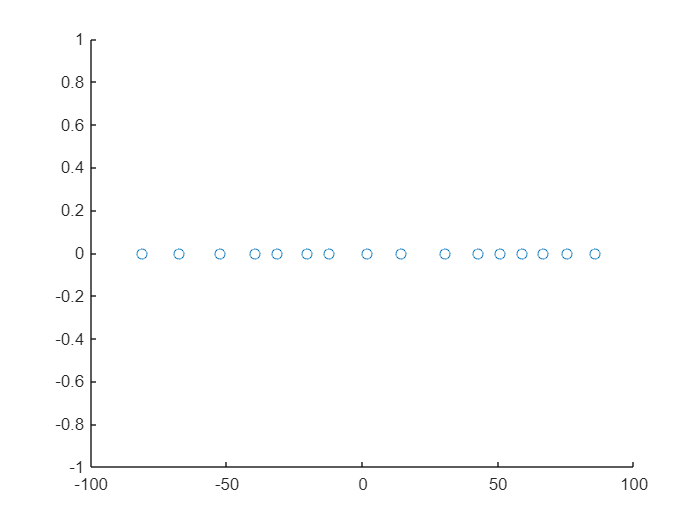

[AAA,idx] = sort(model_points{1}(:,1));
figure ;
scatter(model_points{1}(:,1), model_points{1}(:,2));

i = 7

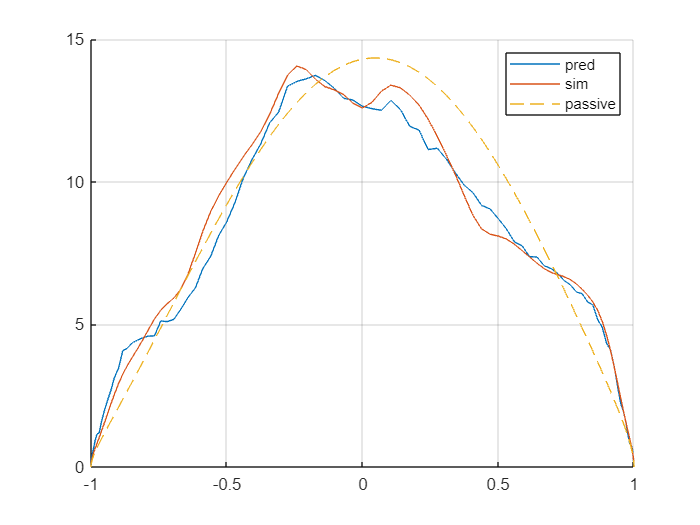

i = 9

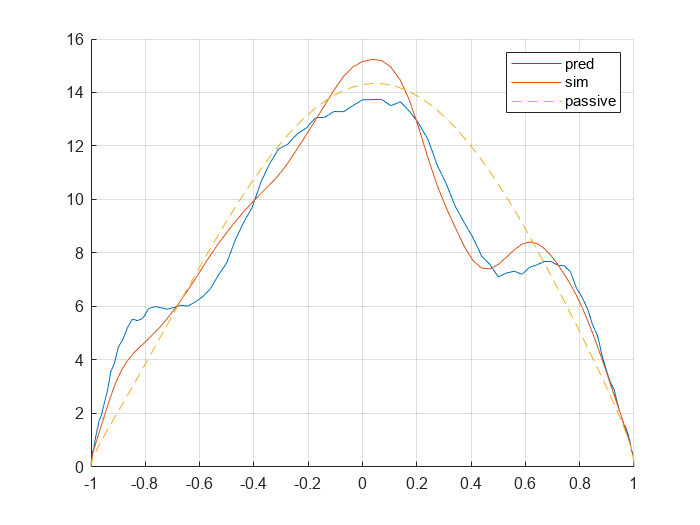

i = 5

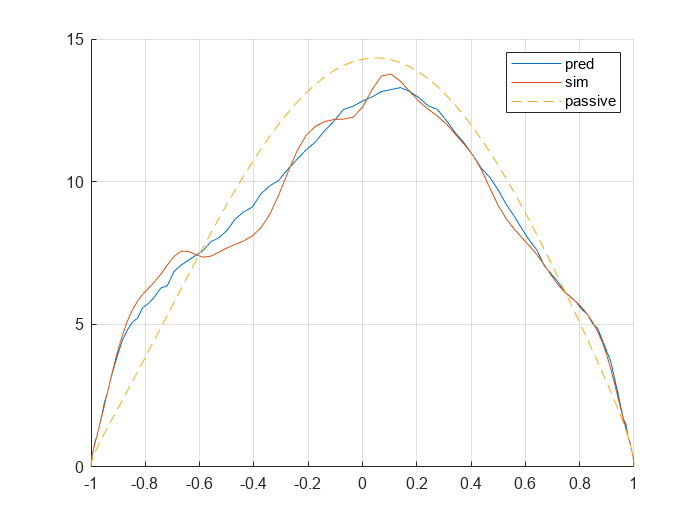

% YPred_mag = predict(magnet, XValidation);
% YPred_phase = predict(phasenet, XValidation);
% YPred_complex = YPred_mag .* exp(1j * YPred_phase);
YPred_complex = YPred;
for j = 1:size(idx([1 2 5]))
    i = idx([1 2 5]);
    i = i(j)
    real_= 1:91;imag_ = 92:182;
    theta = sind(-90:2:90);
    figure ;hold on;
    plot(theta, abs(YPred_complex(i, real_)));
    plot(theta, abs(YValidation(i, real_)));
    plot(theta, abs(g_ave_connect(1,imag_)), '--');
    grid on;
    legend('pred', 'sim', 'passive');
%     ylim([0 20])
    hold off;   
end

YPred_complex = YPred;
Y1 = [real(YPred_complex), imag(YPred_complex)];
Y_val_connect = [real(YValidation), imag(YValidation)];
mean(sum((Y1 - Y_val_connect).^2,2))/91

ans = single
0.7081

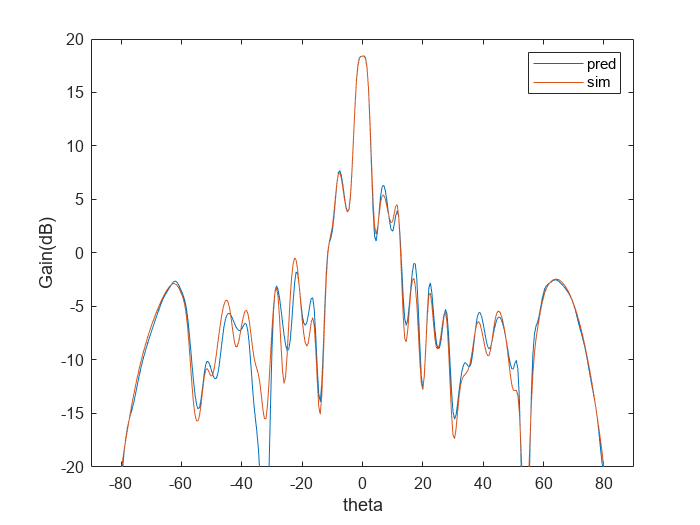

% array syhthesis
ln_all = zeros(K*M +2 , N_elements);
for j = 1:16
    ln_all(:,j) = calculate_ABE_features_1(j, model_points{1}, K, M, Rc, 15, [Inf,Inf], 100, 10);
end
YPred = predict(trainedNet, ln_all.');
YPred_complex = YPred(:, real_) + 1j*YPred(:, imag_);
YPred_complex = YPred_complex.';
% validate data
theta = -90:2:90;F = zeros(91,3);
theta_expect = -90:0.5:90;
N = 16;


theta_scandeg = 0;
phi_scandeg = 0;
u0 = [0,0,0];
u0(1) = sind(theta_scandeg) * cosd(phi_scandeg);
u0(2) = sind(theta_scandeg) * sind(phi_scandeg);

points = model_points{1};k0 = 0.4188;
for n = 1:N
    rn = [points(n,:),0];
    Gn1 = YPred_complex(:, n);
    Gn2 = G_complex_all(:,n);
%     Gn3 = gn_periodic;
    phase_n = k0 * (-dot(rn, u0));
    F(:,1) = F(:,1) + Gn1 .* exp(1j * k0 * (rn(1) * sind(theta.')) + 1j * phase_n);
    F(:,2) = F(:,2) + Gn2 .* exp(1j * k0 * (rn(1) * sind(theta.')) + 1j * phase_n);
%     F(:,3) = F(:,3) + Gn3 .* exp(1j * k0 * (rn(1) * sind(theta.')) + 1j * phase_n);
end
U = abs(F) .^2 /2 /377;
Gain = 4*pi*U/ N; 
Gain = 10 * log10(Gain);
Gain(isnan(Gain)) = -20;
% plot(theta, abs(F) - F_ref);
Gain = interp1(theta,Gain, theta_expect, 'spline');
figure;
hold on;box on;
plot(theta_expect, Gain(:,1));
plot(theta_expect, Gain(:,2));

ylim([-20 20]);xlim([-90 90]);
ylabel("Gain(dB)");xlabel("theta");
legend("pred", 'sim');

% % 残差连接
% 
% 
% lgraph = layerGraph;
% inputLayers = [
%     featureInputLayer(inputSize, 'Name', 'input', 'Normalization', 'zscore')
%     fullyConnectedLayer(hiddenDim, 'Name', 'fc_initial', 'WeightL2Factor', l2Reg, 'BiasL2Factor', l2Reg) % Initial projection
%     reluLayer('Name','relu_initial')
%     ];
% lgraph = addLayers(lgraph, inputLayers);
% 
% % --- Create Residual Blocks ---
% currentLayerOutput = 'relu_initial'; % Output name of the initial layers
% 
% for i = 1:numResidualBlocks
%     blockName = sprintf('resBlock%d', i);
% 
%     % Layers within the residual block
%     blockLayers = [
%         fullyConnectedLayer(hiddenDim, 'Name', [blockName '_fc1'], 'WeightL2Factor', l2Reg, 'BiasL2Factor', l2Reg)
%         batchNormalizationLayer('Name', [blockName '_bn1'])
%         reluLayer('Name', [blockName '_relu1'])
%         dropoutLayer(dropoutProb, 'Name', [blockName '_drop1']) % Optional dropout
% 
%         fullyConnectedLayer(hiddenDim, 'Name', [blockName '_fc2'], 'WeightL2Factor', l2Reg, 'BiasL2Factor', l2Reg)
%         batchNormalizationLayer('Name', [blockName '_bn2'])
%         % Note: ReLU after addition
%     ];
%     lgraph = addLayers(lgraph, blockLayers);
% 
%     % Addition layer for the skip connection
%     addLayer = additionLayer(2, 'Name', [blockName '_add']); % Add two inputs
%     lgraph = addLayers(lgraph, addLayer);
% 
%     % Final ReLU for the block
%     finalReluLayer = reluLayer('Name', [blockName '_relu_final']);
%     lgraph = addLayers(lgraph, finalReluLayer);
% 
%     % --- Connect Layers within the block and the skip connection ---
%     % Connect main path within the block
%     lgraph = connectLayers(lgraph, currentLayerOutput, [blockName '_fc1']); % Input to block's first FC
%     lgraph = connectLayers(lgraph, [blockName '_bn2'], [blockName '_add/in1']); % Main path output to addition layer
% 
%     % Connect skip connection path
%     lgraph = connectLayers(lgraph, currentLayerOutput, [blockName '_add/in2']); % Block input to addition layer
% 
%     % Connect addition layer to final ReLU
%     lgraph = connectLayers(lgraph, [blockName '_add'], [blockName '_relu_final']);
% 
%     % Update the output name for the next iteration/block
%     currentLayerOutput = [blockName '_relu_final'];
% end
% 
% outputLayers = [
%     fullyConnectedLayer(outputSize, 'Name', 'fc_output', 'WeightL2Factor', l2Reg, 'BiasL2Factor', l2Reg) % Final FC layer to get 2 outputs
%     regressionLayer('Name', 'output') % Regression layer for training
%     ];
% lgraph = addLayers(lgraph, outputLayers);
% 
% % Connect the last residual block to the final output layer
% lgraph = connectLayers(lgraph, currentLayerOutput, 'fc_output');